# PHY 329 Final Project

## Ryan Schlimme (eid: rjs4499)

q = @(x) 1/2*(2*x(2).^2 - 2*x(1).^2*x(2).^2 + x(1).^4*x(2).^2 + x(1).^2/4 - x(1)*x(2));

# Contour Plot

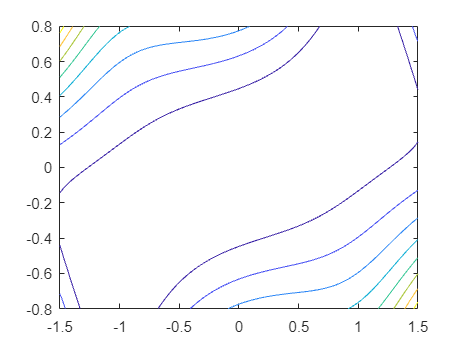

f = @(x1,x2) 1/2*(2*x2.^2 - 2*x1.^2*x2.^2 + x1.^4*x2.^2 + x1.^2/4 - x1*x2);
fcontour(f, [-1.5 1.5 -0.8 0.8])

# Gradient Descent

hold off

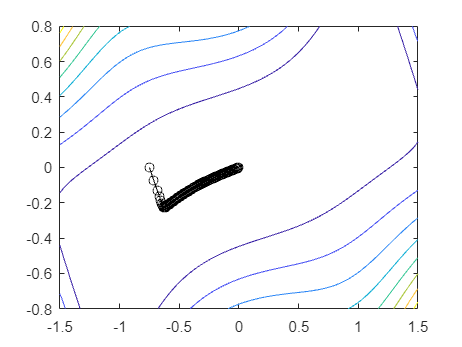

ans = 1.0e-04 *

   -0.3970
   -0.1054


grad_descent([-0.75 0]')

# Runge Kutta

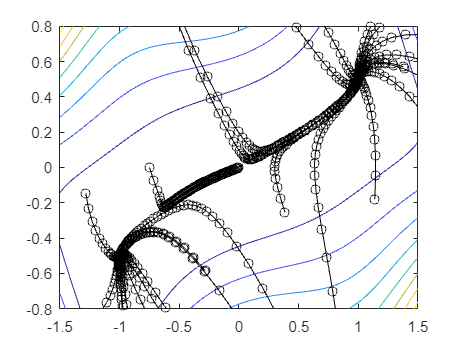

xs = 4.*rand(25,2)-2; % Generate random point pairs between -2 and 2

dx1 = @(t,x1,x2) (1-x1.^2)*x2;
dx2 = @(t,x1,x2) x1/2-x2;

for i = 1:1:25
    [t,x,y] = rk4sys(dx1, dx2, [0,100], xs(i,1), xs(i,2), 0.2);
    hold on;
    figure(1); plot(x,y,'ko-')
    xlim([-1.5 1.5])
    ylim([-0.8 0.8])
end

hold off

# Define Our Functions

% Fourth-RK System

function [t,x,y] = rk4sys(e, f, tspan, x0, y0, h, varargin)
ti = tspan(1);tf = tspan(2);
if ~(tf>ti), error('upper limit must be greater than lower'), end
t = (ti:h:tf)'; n = length(t);
if t(n)<tf
    t(n+1) = tf;
    n = n + 1;
end
y = y0*ones(n,1);
x = x0*ones(n,1);
for i = 1:n-1
    k1 = e(t(i),x(i),y(i));
    l1 = f(t(i),x(i), y(i));
    k2 = e(t(i)+0.5*h, x(i)+0.5*k1*h, y(i)+0.5*l1*h);
    l2 = f(t(i)+0.5*h, x(i)+0.5*k1*h, y(i)+0.5*l1*h);
    k3 = e(t(i)+0.5*h, x(i)+0.5*k2*h, y(i)+0.5*l2*h);
    l3 = f(t(i)+0.5*h, x(i)+0.5*k2*h, y(i)+0.5*l2*h);
    k4 = e(t(i)+h, x(i)+k3*h, y(i)+l3*h);
    l4 = f(t(i)+h, x(i)+k3*h, y(i)+l3*h);
    x(i+1) = x(i) + 1/6*(k1+2*k2+2*k3+k4)*h;
    y(i+1) = y(i) + 1/6*(l1+2*l2+2*l3+l4)*h;
end
end

% Gradient Descent
function [xopt,fopt,niter,gnorm,dx] = grad_descent(varargin)
% grad_descent.m demonstrates how the gradient descent method can be used
% to solve a simple unconstrained optimization problem. Taking large step
% sizes can lead to algorithm instability. The variable alpha below
% specifies the fixed step size. Increasing alpha above 0.32 results in
% instability of the algorithm. An alternative approach would involve a
% variable step size determined through line search.
%
% This example was used originally for an optimization demonstration in ME
% 149, Engineering System Design Optimization, a graduate course taught at
% Tufts University in the Mechanical Engineering Department. A
% corresponding video is available at:
% 
% http://www.youtube.com/watch?v=cY1YGQQbrpQ
%
% Author: James T. Allison, Assistant Professor, University of Illinois at
% Urbana-Champaign
% Date: 3/4/12
if nargin==0
    % define starting point
    x0 = [3 3]';
elseif nargin==1
    % if a single input argument is provided, it is a user-defined starting
    % point.
    x0 = varargin{1};
else
    error('Incorrect number of input arguments.')
end
% termination tolerance
tol = 1e-6;
% maximum number of allowed iterations
maxiter = 1000;
% minimum allowed perturbation
dxmin = 1e-6;
% step size ( 0.33 causes instability, 0.2 quite accurate)
alpha = 0.1;
% initialize gradient norm, optimization vector, iteration counter, perturbation
gnorm = inf; x = x0; niter = 0; dx = inf;
% define the objective function:
f = @(x1,x2) 1/2*(2*x2.^2 - 2*x1.^2*x2.^2 + x1.^4*x2.^2 + x1.^2/4 - x1*x2);
% plot objective function contours for visualization:
figure(1); clf; fcontour(f,[-1.5 1.5 -0.8 0.8]); hold on
% redefine objective function syntax for use with optimization:
f2 = @(x) f(x(1),x(2));
% gradient descent algorithm:
while and(gnorm>=tol, and(niter <= maxiter, dx >= dxmin))
    % calculate gradient:
    g = grad(x);
    gnorm = norm(g);
    % take step:
    xnew = x - alpha*g;
    % check step
    if ~isfinite(xnew)
        display(['Number of iterations: ' num2str(niter)])
        error('x is inf or NaN')
    end
    % plot current point
    plot([x(1) xnew(1)],[x(2) xnew(2)],'ko-')
    refresh
    % update termination metrics
    niter = niter + 1;
    dx = norm(xnew-x);
    x = xnew;
end
xopt = x;
fopt = f2(xopt);
niter = niter - 1;
% define the gradient of the objective
function g = grad(x)
g = [-4*x(1)*x(2).^2+4*x(1).^3*x(2).^2+x(1)/2-x(2)
    4*x(2)-4*x(1).^2*x(2)+2*x(1).^4*x(2)-x(1)];
end
end